% y*exp(x)*dx+(y+exp(x))*dy=0

clear
% 1)
% y'=-y*exp(x)/(y+exp(x))
syms x y(x)
eqn=diff(y(x))==-y*exp(x)/(y+exp(x))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{{\mathrm{e}}^{x}\,y\left(x\right)}{{\mathrm{e}}^{x}+y\left(x\right)}$$

ySol=dsolve(eqn)

$$ySol = \left(\begin{array}{c} \sqrt{C_{1}+{\mathrm{e}}^{2\,x}}-{\mathrm{e}}^{x}\\ -{\mathrm{e}}^{x}-\sqrt{C_{1}+{\mathrm{e}}^{2\,x}} \end{array}\right)$$

%    (C13 + exp(2*x))^(1/2) - exp(x)
%  - exp(x) - (C13 + exp(2*x))^(1/2)

% 2)
syms x y
P(x,y)=y*exp(x), Q(x,y)=y+exp(x)

$$P(x, y) = y\,{\mathrm{e}}^{x}$$

$$Q(x, y) = y+{\mathrm{e}}^{x}$$

f=diff(P,y)-diff(Q,x)

$$f(x, y) = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P(x,y),x)+C(y)

$$U = C\left(y\right)+y\,{\mathrm{e}}^{x}$$

% C(y) + y*exp(x)
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)+{\mathrm{e}}^{x}$$

% diff(C(y), y) + exp(x)
dCy=simplify(dUy-Q)

$$dCy(x, y) = \frac{\partial }{\partial y}C\left(y\right)-y$$

% diff(C(y), y) - y
C(y)=int(y,y)

$$C(y) = \frac{y^{2}}{2}$$

% y^2/2 + C1
% U=y*exp(x)+y^2/2 + C1
% y*exp(x)+y^2/2 = C2

% 3)
x0=0;y0=0;
U=simplify(int(P(x,y),x,x0,x)+int(subs(Q(x,y),x,x0),y,y0,y))

$$U = \frac{y^{2}}{2}+{\mathrm{e}}^{x}\,y$$

syms C
eq2=U==C

$$eq2 = \frac{y^{2}}{2}+{\mathrm{e}}^{x}\,y=C$$

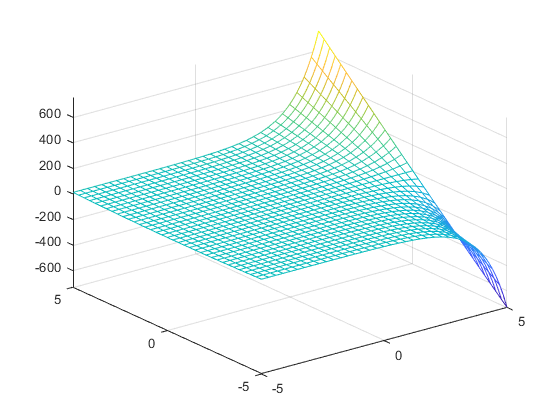

fmesh(U)